# Create and Customize Pie Charts

Pie charts are circular statistical graphs that are divided into slices.

### Read Cars Data

We will use "`carbig.mat" `to demonstrate how to create and customize pie charts. The MAT-file contains various measurement data of 406 models of cars such as MPG, Horsepower, Displacement, etc. released in different countries between 1970 and 1982. 

load("carbig.mat")

### Basic Pie Chart

View the distribution in the number of cylinders for the 406 cars and observe the proportion of each type. 

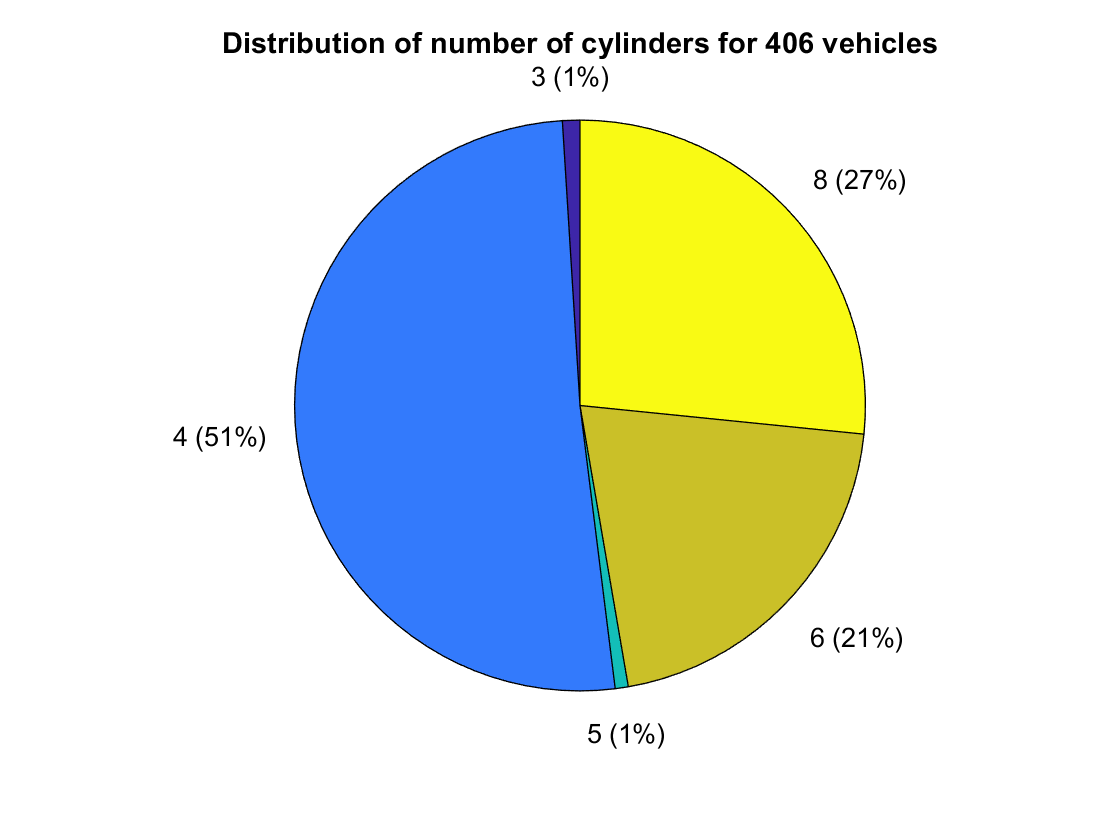

pie(categorical(Cylinders));
title("Distribution of number of cylinders for 406 vehicles")

## Customization

### Explode Pie Sections

To "explode" sections of the pie chart, use the second argument to pie. This allows certain pie chart segments to be highlighted. If the percentage values are undesired, labels can also be explicitly specified as an input argument.

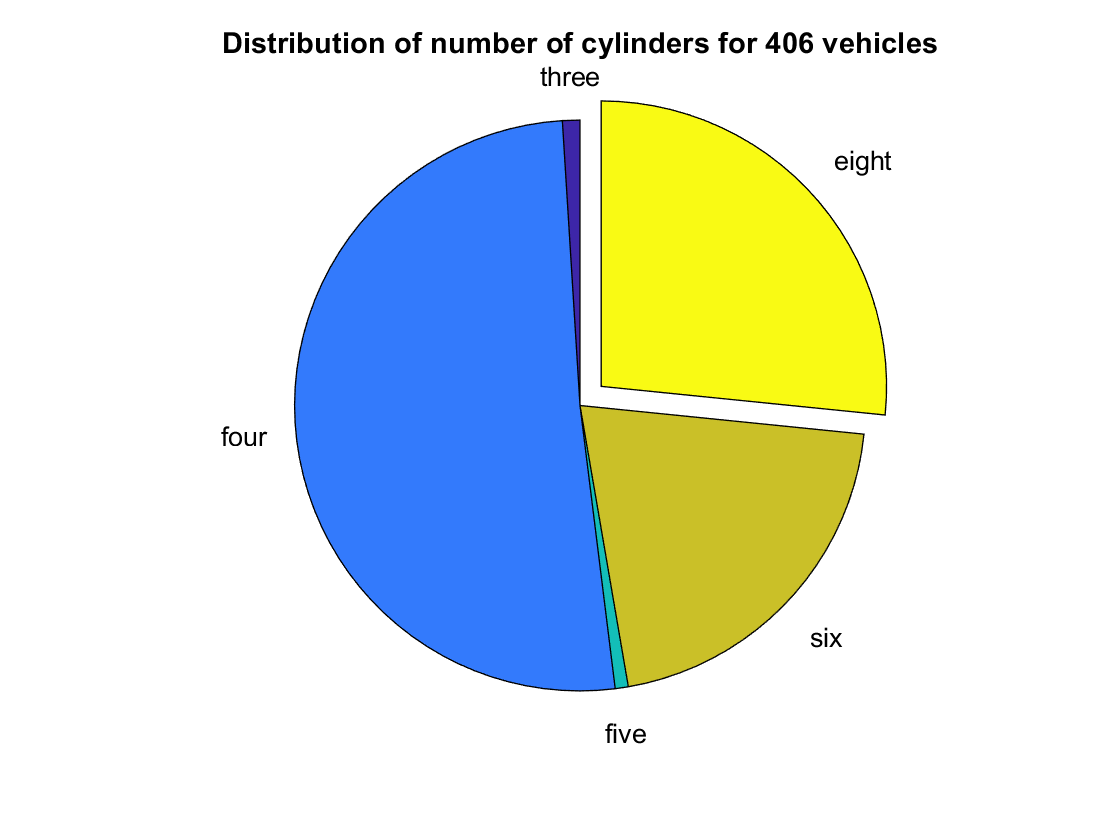

explodeInd = 5; % Specify index for exploded segment
explodeVec = zeros(1,5);
explodeVec(explodeInd) = 1;
labels = ["three","four","five","six","eight"];

figure
p = pie(categorical(Cylinders),...
    explodeVec,...  % Specify vector to indicate which segments should be exploded
    labels);        % Specify labels for each segment
title("Distribution of number of cylinders for 406 vehicles")

### Change Individual Segment Color

If a particular section of the pie chart needs to be highlighted distinctly, individual pie chart segment colors can be changed. The `pie` function call returns a handle containing 2*n objects where n is the number of segments on the pie chart. The first n objects represent the Patch objects that form the colored segments while the second n objects represent the Text objects that form the segment labels.

By accessing the associated Patch object and its *FaceColor* property, the segment color can be changed. Specify the gray colormap to distinguish the section even more.

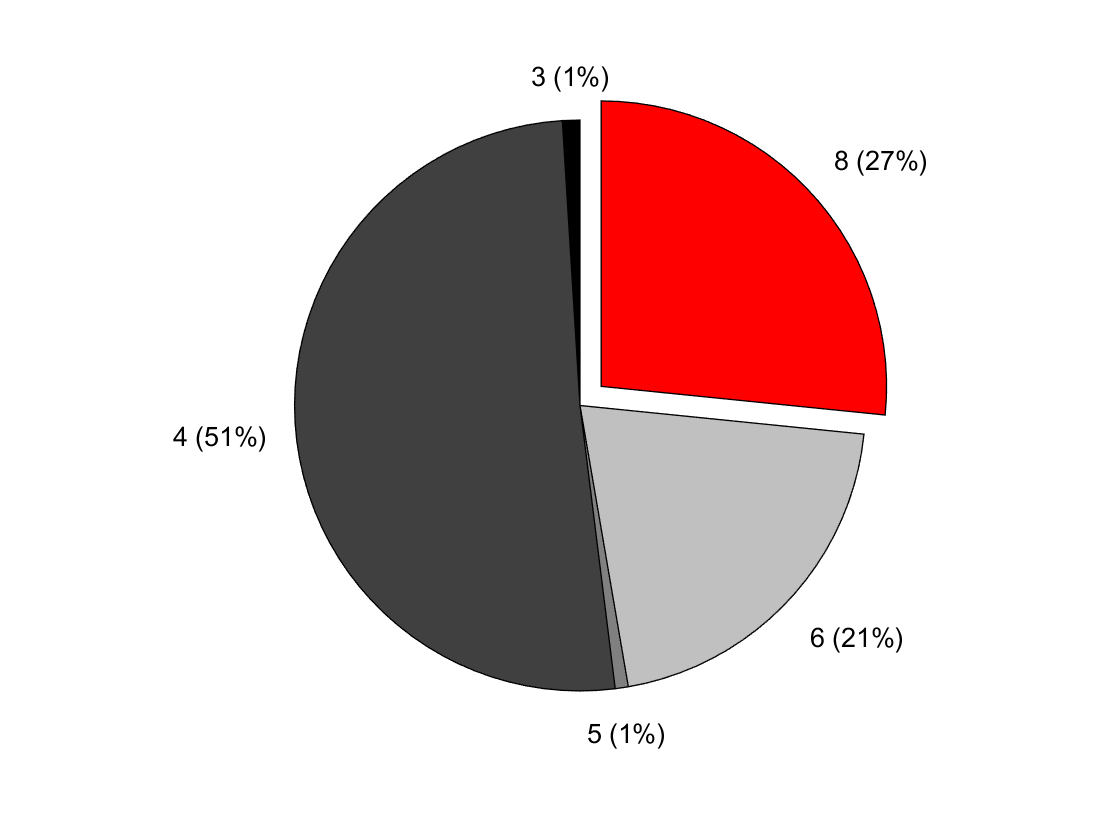

figure
p1 = pie(categorical(Cylinders),explodeVec);

patchHandles = findobj(p1,"Type","Patch");  % Access the Patch objects
patchHandles(5).FaceColor = "r";            % Specify the FaceColor property of the desired Patch object 
colormap("gray")    

### Customize Pie Chart Labels

Pie chart labels can be customized to include the word "Cylinder" and still retain the percentage. Access the Text objects through the plot handle and modify the *String* properties for each label in a for loop using dot notation.

p2 = pie(categorical(Cylinders));

pText = findobj(p2,"Type","text");   % Access Text objects
defaultLabels = get(pText,"String"); % Obtain default labels from Text objects
txt = ' Cylinders'; 
for i = 1:length(pText)
    pText(i).String = [defaultLabels{i}(1) txt defaultLabels{i}(2:end)]; % Insert desired text into label
end
title("Distribution of number of cylinders for 406 vehicles")

### Change Chart Colormap

There are several default colormaps specified in MATLAB, some are shown in the drop down menu.

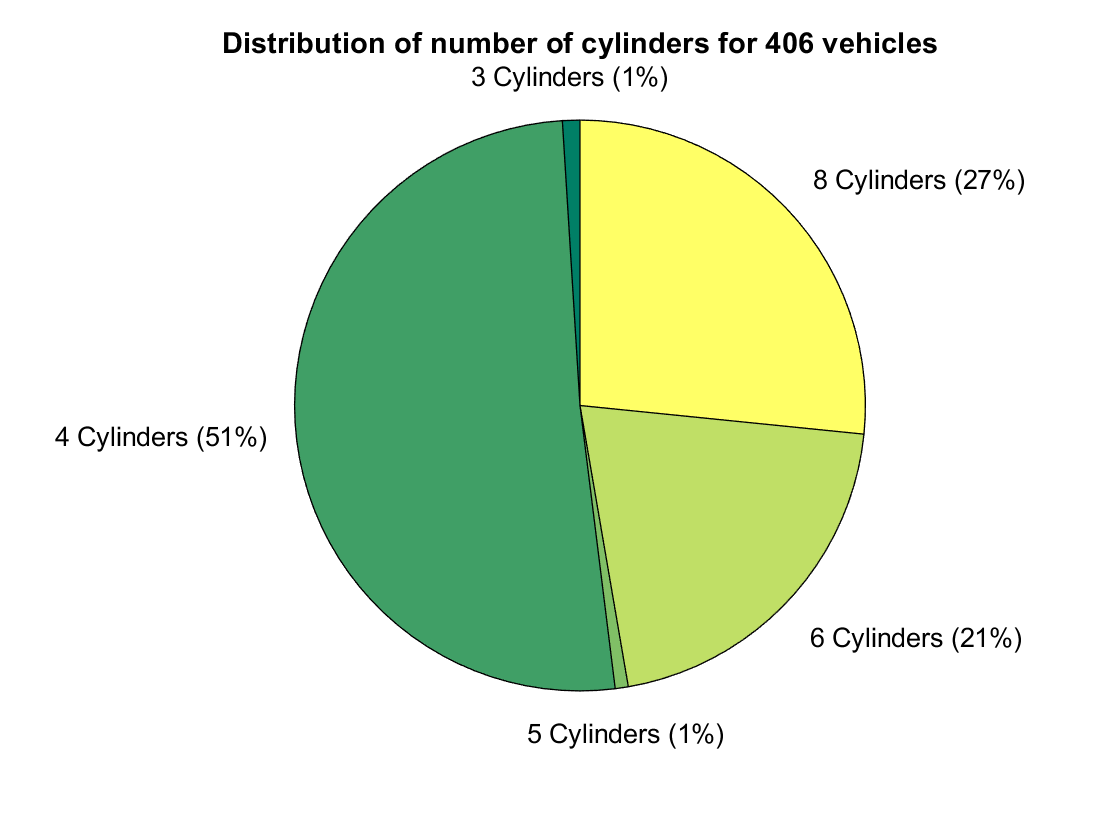

colormap("summer"); % Specify colormap

## **Additional Information**

### **Get All Patch and Text Properties**

Graphics objects in MATLAB have many properties. To see all the properties of a Patch or Text object, uncomment the following code. View or modify these properties using dot notation.

% get(p(1)) % View Patch object properties
% get(p(6)) % View Text object properties

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[pie](https://www.mathworks.com/help/matlab/ref/pie.html)

Copyright (c) 2021, The MathWorks, Inc.